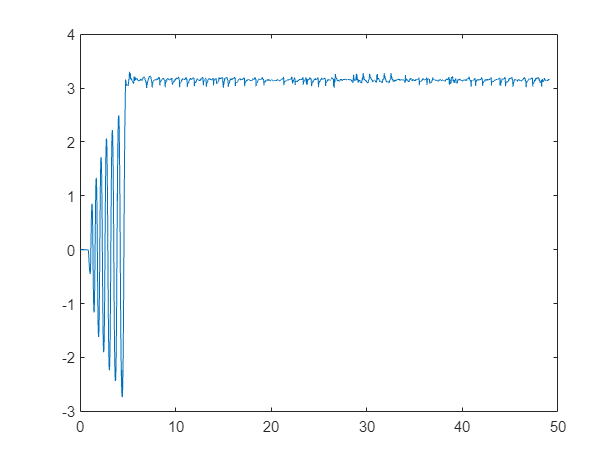

clc; clear; close all;
load("rmsTest.mat")
triggerTimeIndex = 942;

rmsTest.one.baseAngle(1:2100) =[];
rmsTest.one.time(1:2100) =[];
rmsTest.one.time = rmsTest.one.time - rmsTest.one.time(1);


rmsTest.one.pendAngleZeroDwn(1:2100) =[];
rmsTest.one.pendAngleZeroUp(1:2100) =[];
rmsTest.one.timeTrigger(1:2100) =[];
rmsTest.one.Current(1:2100) =[];
rmsTest.one.Current = rmsTest.one.Current + 0.033;



plot(rmsTest.one.time, rmsTest.one.pendAngleZeroDwn)

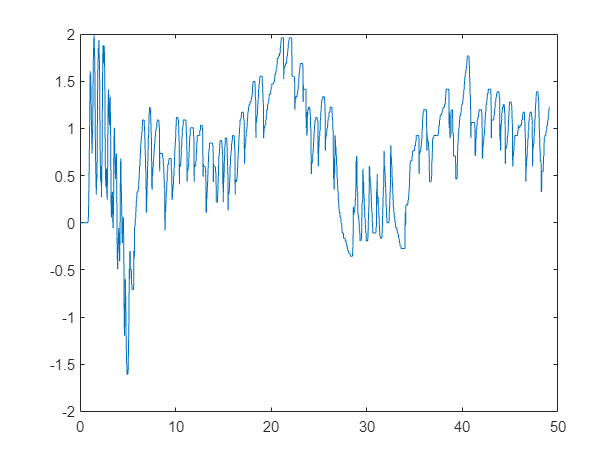

plot(rmsTest.one.time, rmsTest.one.baseAngle)

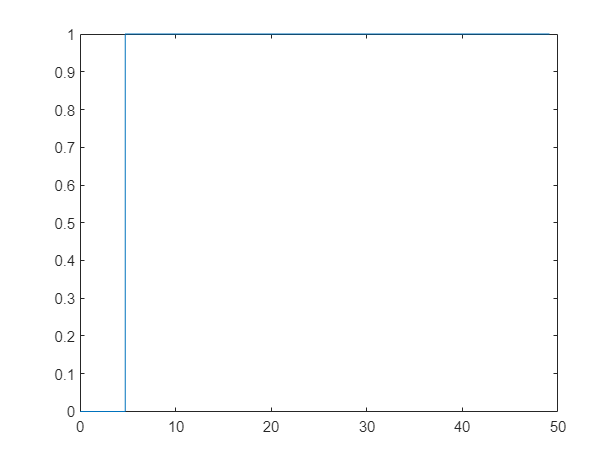

plot(rmsTest.one.time, rmsTest.one.timeTrigger)

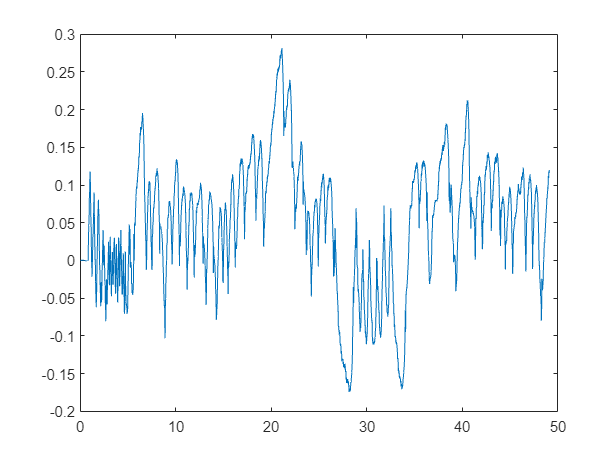

plot(rmsTest.one.time, rmsTest.one.Current)

Plotting for the report pendulum

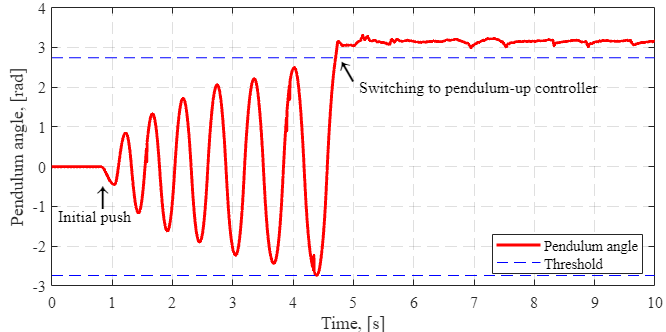

fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot

%Data Point Formatting
fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];
% Specifying the position of the lower left corner + the width and height of the frame
lengthOfPltIndex = 2000;
lengthOfPltTime = rmsTest.one.time(lengthOfPltIndex);
hold on
plt1 = plot(rmsTest.one.time(1:lengthOfPltIndex), rmsTest.one.pendAngleZeroDwn(1:lengthOfPltIndex));
plt1.Color = 'r';    % y, m, c, r, g, b, w, k,
plt1.LineStyle ='-'; % '-', '--', ':', '-.'
plt1.LineWidth  = LW2;

 plt2 = plot([0, lengthOfPltTime], [pi-0.4, pi-0.4]);
 plt2.Color = 'b';
 plt2.LineStyle = '--';

 plt3 = plot([0, lengthOfPltTime], [-pi+0.4, -pi+0.4]);
 plt3.Color = 'b';
 plt3.LineStyle = '--';

 %plt2.LineWidth = LW1;
% plt2.MarkerSize = 8;
% plt2.MarkerEdgeColor = 'r';
% plt2.MarkerFaceColor = [0.5,0.5,0.5]; % RGB code
% plt2.MarkerIndices  = 1:450:length(y2);


%Axis Text Formatting 
% ax.XColor = 'r'
ax.Units = 'centimeters';
ax.GridLineStyle = '--';                % '-' '--' ':' '-.'
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
ax.XTick = [0:1:10];                    % Divisions on axes
ax.YTick = [-5:1:5];                    % Divisions on axes
%axis([tmin, tmax, -5, 5]);              % lower and upper limit
%Axis Labels and Legend 
label_x = xlabel('Time, [s]'); 
label_x.Units = "centimeters"; 
label_x.Position = [xlabel_x, xlabel_y]; 
 
label_y = ylabel('Pendulum angle, [rad]'); 
label_y.Units = "centimeters"; 
label_y.Position = [ylabel_x, ylabel_y]; 
 
leg = legend('Pendulum angle', 'Threshold'); 
leg.Location = "southeast"; 

% First arrow
arrow1 = text(); 
arrow1.String = '\rightarrow'; 
arrow1.Position = [0.8,-1.2]; 
arrow1.FontSize = 20; 
arrow1.Rotation = 90;

text1 = text(); 
text1.String = 'Initial push'; 
text1.Position = [0.1,-1.25]; 
text1.FontName = 'Times New Roman'; 
text1.FontSize = AxisFontSize; 

%Second arrow
arrow2 = text(); 
arrow2.String = '\rightarrow'; 
arrow2.Position = [5,2]; 
arrow2.FontSize = 20; 
arrow2.Rotation = 120;

text2 = text(); 
text2.String = 'Switching to pendulum-up controller'; 
text2.Position = [5.1,2]; 
text2.FontName = 'Times New Roman'; 
text2.FontSize = AxisFontSize; 


hold off
grid on
box on